Supplements consensus_real_data.txt

Visualize block representation of barcode island. 

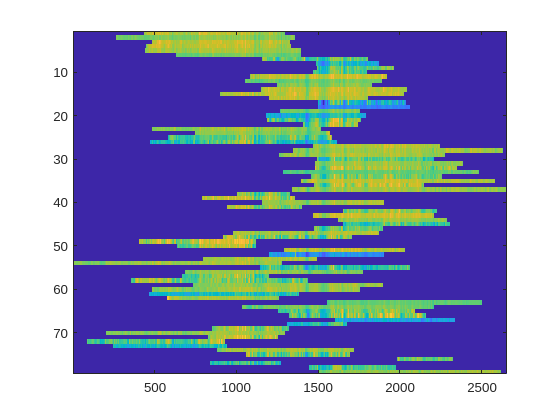

ix = 1;
cgenid = cGenAll{ix}.idx;
bgC = barcodeGen(cGenAll{ix}.idx);

[outBarsCorrectLengthRescale] = barcodes_to_scaled(barcodeGen(cGenAll{ix}.idx),cGenAll{ix}.comparisonStruct, []);

consensusToPlot1 = outBarsCorrectLengthRescale(2:end,:);

figure,imagesc(consensusToPlot1)

Now pairwise overlaps. To speed up, we could sort first so that we don't have a quadratic complexity

tic
wmin = 300;
% pairwise compare
allscores = zeros(size(consensusToPlot1,1),size(consensusToPlot1,1));
for i=1:size(consensusToPlot1,1)-1
    for j=i+1:size(consensusToPlot1,1)        
        overlapPx = ~isnan(consensusToPlot1(i,:)).*~isnan(consensusToPlot1(j,:));
        if sum(overlapPx) > wmin %if overlap more than a given. Could also convert to Stouffer here
            allscores(i,j) = zscore(consensusToPlot1(i,logical(overlapPx)),1)*zscore(consensusToPlot1(j,logical(overlapPx)),1)'/sum(overlapPx);
        else
%             allscores(i,j) = 0.01; % tempfix - small score so consensus would still work
        end
    end
end
toc

Elapsed time is 0.142383 seconds.


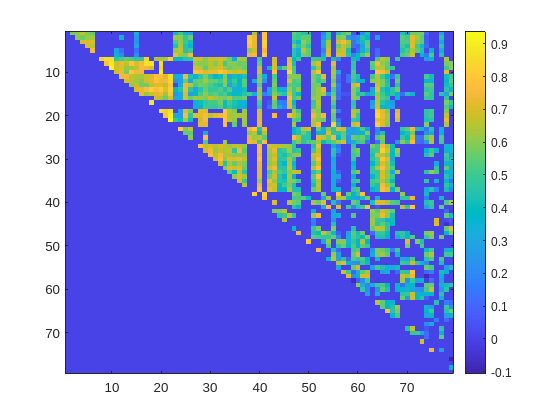

figure,imagesc(allscores);colorbar

Dendogram. Make sure to include all barcodes (including transitive matching)

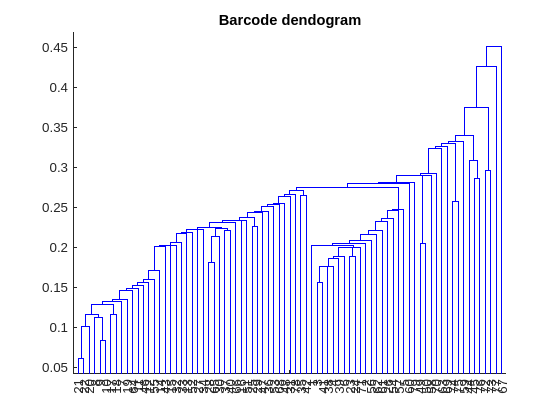


allscores2 = allscores'+allscores;
% square form
y = squareform(allscores2);


Z = linkage(1-y); % this links groups, but we also want to know which elements exactly are linked

% create groups for the scores
[groups,curElts] = consensus_groups(allscores,bgC,Z);

figure % can plot the dendogram
dendrogram(Z,0); title('Barcode dendogram')

**Consensus cluster**

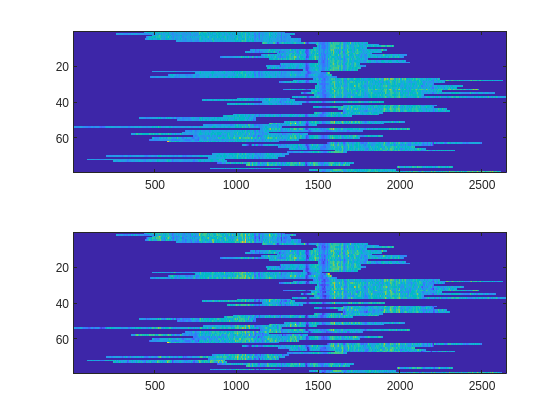

[scoreAlignedData] = consensus_cluster(consensusToPlot1,Z,barcodeGen(cGenAll{ix}.idx),curElts,groups);

figure,tiledlayout(2,1)
nexttile
imagesc(scoreAlignedData)
nexttile
imagesc(outConsensus{ix})

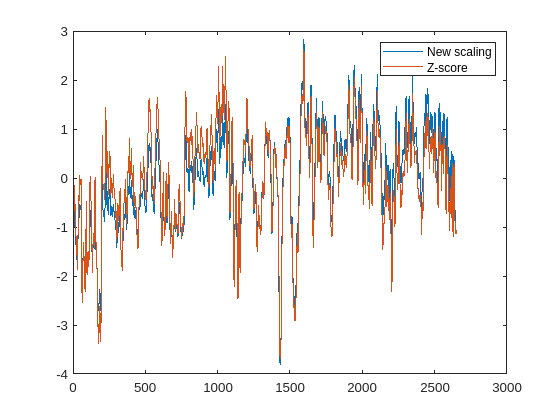

con1 = nanmean(scoreAlignedData);
conz = nanmean(outConsensus{ix});
figure,plot((con1-nanmean(con1))/nanstd(con1,1))
hold on,plot((conz-nanmean(conz))/nanstd(conz,1))
legend({'New scaling','Z-score'})